close all; clear; clc;

# Fixed sample rate- UpDown test

**filename**: NAME.mlx

**keywords:** 

**file created by:** {YYYYMMDD, NAME}

**last updated on:** {YYYYMMDD}

**primary purpose:** {Enter the primary purpose and primary input and output variables.}

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:** Rotational Speed was calculated in RPM, need to convert to rad/sec

Don't think I tore the load cell or voltage before running tests

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002285947263;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the "servo" column was deleted beforehand

load('UpDownTest.mat');
time = UpDownTest(:,1);          % [sec]
ESC_us = UpDownTest(:,2);        % [micro sec] (this is how quickly the ESC is providing voltage to the motor -- translates to throttle% ?
Q = UpDownTest(:,3);             % [ft.lbf]
T = UpDownTest(:,4);             % [lbf]
Input_V = UpDownTest(:,5);       % [Volts]
Input_A = UpDownTest(:,6);       % [Amps]
rot_speed_RPM = UpDownTest(:,7);     % [rad/sec]
% Convert RPM to rad/sec
rot_speed = rot_speed_RPM .* (pi/30);

P_in_W = UpDownTest(:,8);        % [Watts]
P_out_W = UpDownTest(:,9);        % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;     % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;       % [ft.lbf/sec]

Motor_Eff = UpDownTest(:,10);    % [%]
Prop_Eff = UpDownTest(:,11);     % [lbf/Watts]
Overall_Eff = UpDownTest(:,12);  % [lbf/Watts]  
Motor_Temp = UpDownTest(:,13);   % [F]


## Thrust, Power, and Torque Coefficents

[C_T] = Thrust_Coefficient(T,p,area,rot_speed,radius);
[C_P] = Power_Coefficient(P_out,p,area,rot_speed,radius);
[C_Q] = Torque_Coefficient(Q,p,area,rot_speed,radius);

## Plots

{This is the section for generating output tables, plots, etc.}

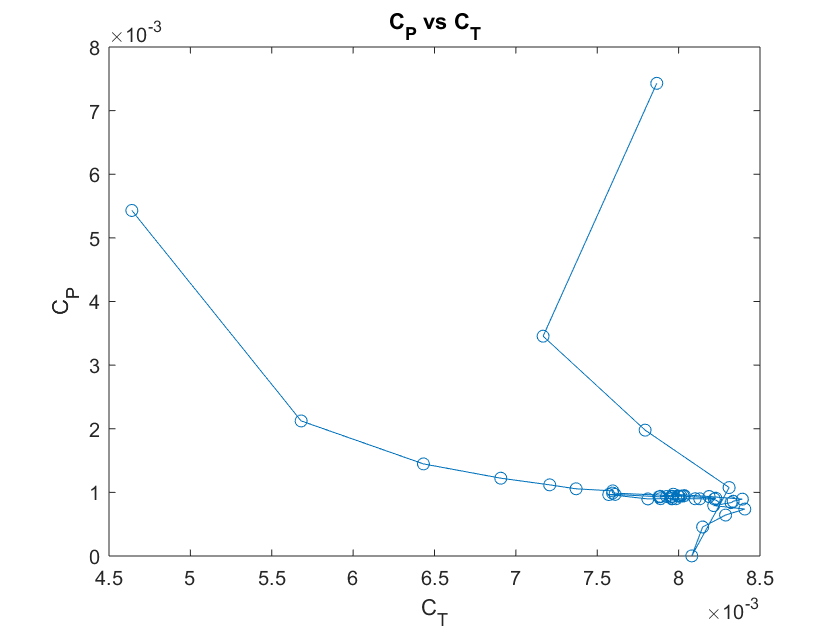




figure(1)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

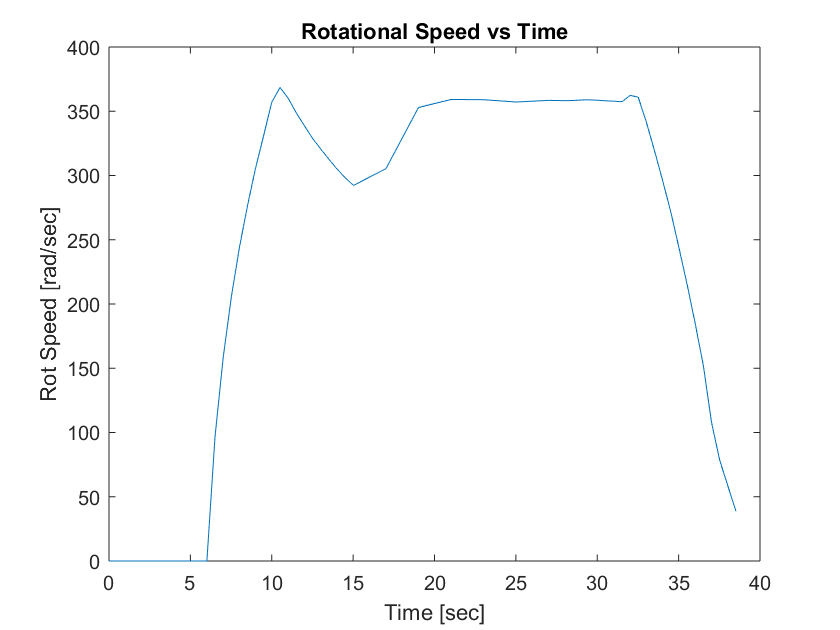

figure(2)
plot(time, rot_speed);
title('Rotational Speed vs Time'); xlabel('Time [sec]'); ylabel('Rot Speed [rad/sec]')

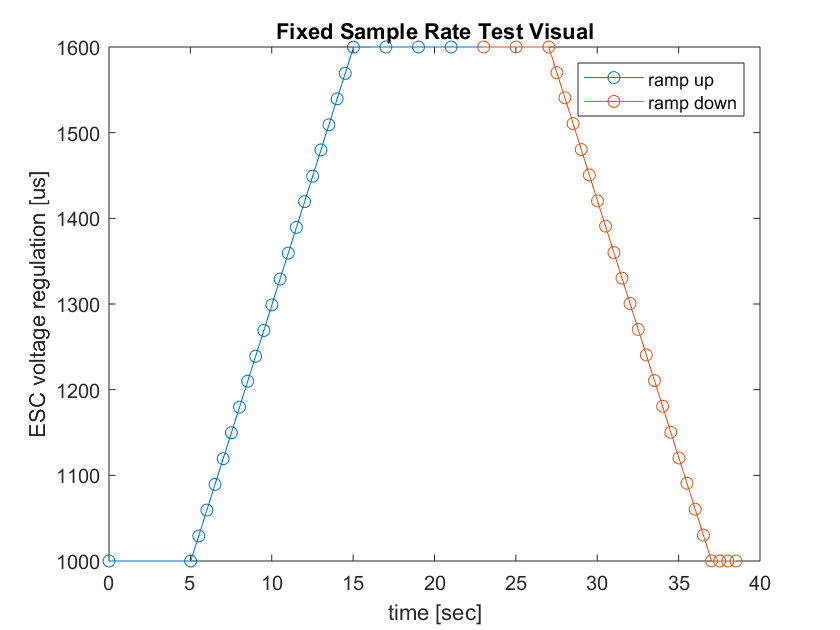

x = (1:26);
y = (26:51);
figure(3)
plot(time(x), ESC_us(x), 'o-', time(y), ESC_us(y), 'o-'); title('Fixed Sample Rate Test Visual'); 
xlabel('time [sec]'); ylabel('ESC voltage regulation [us]');
legend('ramp up','ramp down');

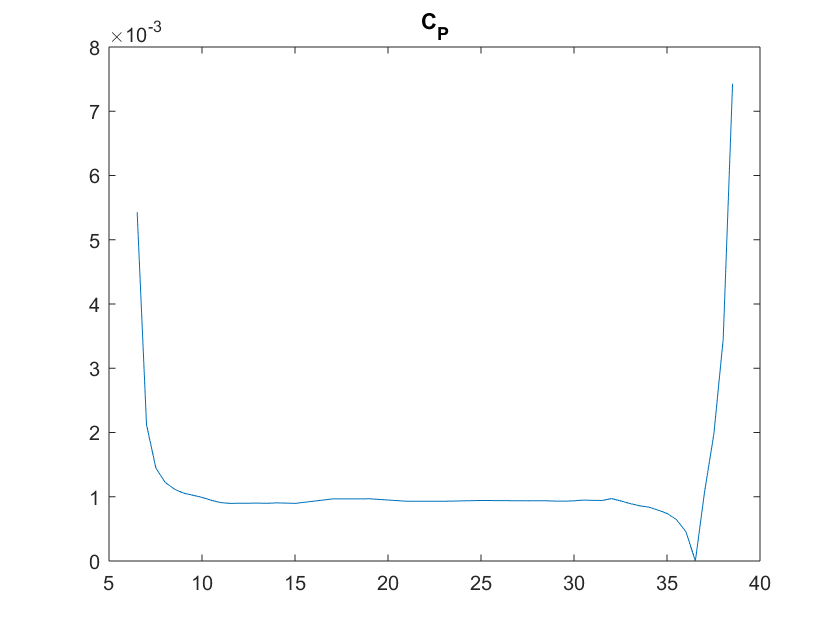




figure(4)
plot(time, C_P);
title('C_P');

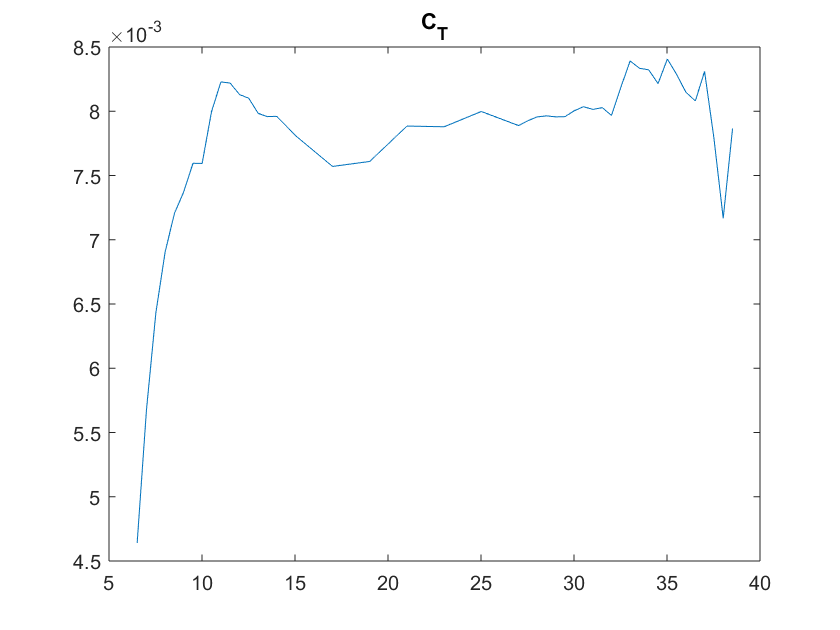


figure(5)
plot(time, C_T);
title('C_T');

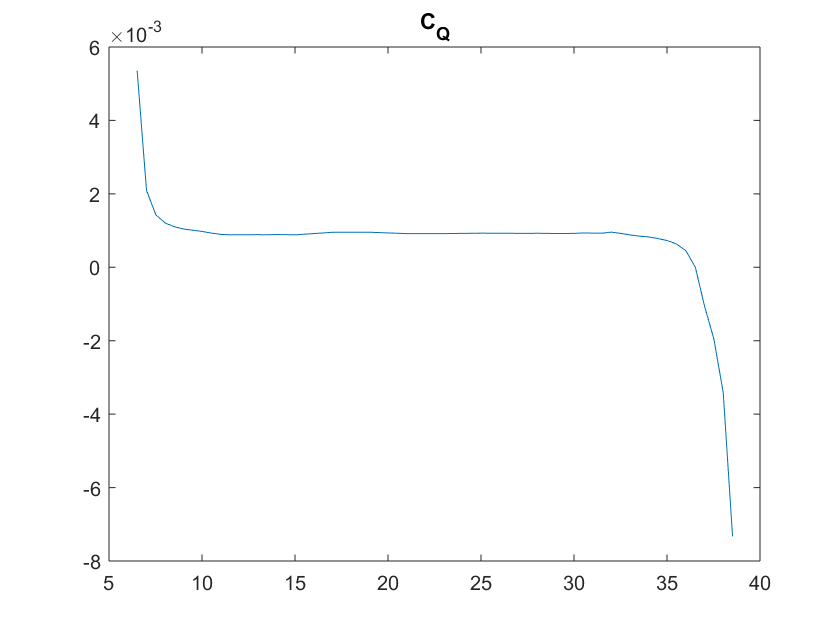


figure(6)
plot(time, C_Q);
title('C_Q');

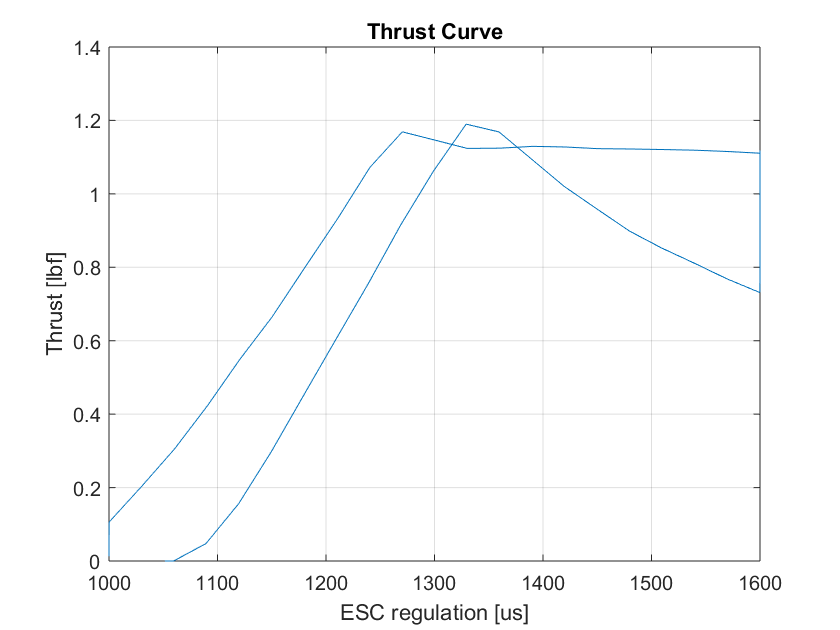

figure(7)
plot(ESC_us, T);
title('Thrust Curve'); xlabel('ESC regulation [us]'); ylabel('Thrust [lbf]'); 
grid('on'); ylim([0,1.4]);

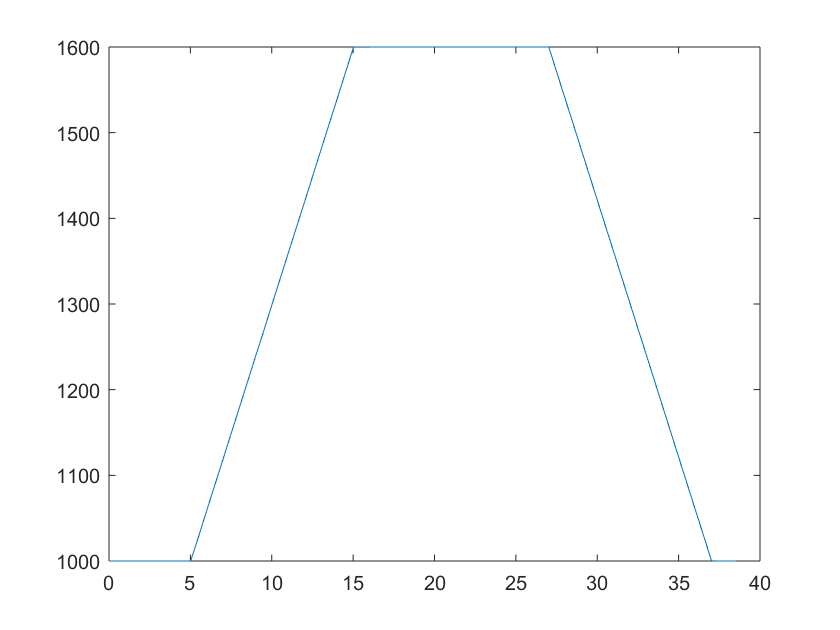




% This plot shows the function of the test
figure(8)
plot(time, ESC_us);